Ewell lab, 2025 gt

Pipeline to reproduce Figure 6 about heading-direction tuning of hippocampal neurons. The pipeline relies on the output main_getHDCCells.m script in the *Heading direction GT\GetHDCells *folder. Maze is divided into 8 angular bins that corresponds to 8 walls of the maze, and angular tuning is calculated (length of Rayleigh-vector). Then Ca events are shuffed 500 times and tuning is recalculated. Cell is considered as heading-direction cell, if it has significant tuning and the vector length is at least 0.4. Cell must be active at least 10 times during the session. Similar table is created as for place cells and place fields that is located in the HDanalysis.mat file.

main_path = "G:\";
main_path

main_path = "G:\"

warning('off') %turn off warnings
addpath(strcat(main_path, "Discrimination 2025 CodeBase\Heading direction GT\GetHDCells"))
addpath(strcat(main_path, "Discrimination 2025 CodeBase\Heading direction GT\VectorRemapping"))

First, load data and get properties of heading-direction cells.

% all discrimination session
workdir_d = [strcat(main_path, "\CA1 miniscope data\M119\TrainingD11\")  strcat(main_path,"\CA1 miniscope data\M120\TrainingD11\")  strcat(main_path,"\CA1 miniscope data\M292\TrainingD6\")  strcat(main_path,"\CA1 miniscope data\M319\TrainingD7\") strcat(main_path,"\CA1 miniscope data\M231\TrainingD9\") strcat(main_path,"\CA1 miniscope data\M314\Training_Separation_D5\") strcat(main_path,"\CA1 miniscope data\M316\Training_Separation_D6\")  strcat(main_path,"\CA1 miniscope data\M318\Training_Separation_D4\") strcat(main_path,"\CA1 miniscope data\M210\TrainingD17\")];
% all generalization session
workdir_g = [strcat(main_path, "\CA1 miniscope data\M119\GroupingD6\") strcat(main_path, "\CA1 miniscope data\M120\GroupingD6\") strcat(main_path, "\CA1 miniscope data\M292\GroupingD3\") strcat(main_path, "\CA1 miniscope data\M319\GroupingD4\") strcat(main_path, "\CA1 miniscope data\M231\GroupingD5\") strcat(main_path, "\CA1 miniscope data\M314\GroupingD3\") strcat(main_path, "\CA1 miniscope data\M316\GroupingD3\") strcat(main_path, "\CA1 miniscope data\M318\GroupingD3\") ];
discrimination = [1 1 1 1 2 2 2 2 1];
grouping = [2 2 2 2 1 1 1 1 0];
OverlappingWall = [2 2 1 1 2 1 2 1 1];
Sex = ["f" "f" "f" "m" "f" "m" "m" "m"];
colors = ["#46bb91" "#93EB74" "#BCEAC5" "#9576b4" "#875FEA" "#D093EB" ];
SaveExamples = 0;
binCenter = -157.5:45:157.5;
wallsDir = ["SW", "W", "NW", "N", "NE", "E", "SE", "S"];

LightBins_d = [5 6; 3 4]; % walls where the light is located - if reward overlaps, that wall is not included in the reward analysis
[All_d, Cohort_d, Individual_d]= WrapVectorRemap3_FINAL(workdir_d, discrimination, LightBins_d);

G:\\CA1 miniscope data\M119\TrainingD11\
G:\\CA1 miniscope data\M120\TrainingD11\
G:\\CA1 miniscope data\M292\TrainingD6\
G:\\CA1 miniscope data\M319\TrainingD7\
G:\\CA1 miniscope data\M231\TrainingD9\
G:\\CA1 miniscope data\M314\Training_Separation_D5\
G:\\CA1 miniscope data\M316\Training_Separation_D6\
G:\\CA1 miniscope data\M318\Training_Separation_D4\
G:\\CA1 miniscope data\M210\TrainingD17\


LightBins_g = [1 2; 7 8];
[All_g, Cohort_g, Individual_g]= WrapVectorRemap3_FINAL(workdir_g, discrimination, LightBins_g);

G:\\CA1 miniscope data\M119\GroupingD6\
G:\\CA1 miniscope data\M120\GroupingD6\
G:\\CA1 miniscope data\M292\GroupingD3\
G:\\CA1 miniscope data\M319\GroupingD4\
G:\\CA1 miniscope data\M231\GroupingD5\
G:\\CA1 miniscope data\M314\GroupingD3\
G:\\CA1 miniscope data\M316\GroupingD3\
G:\\CA1 miniscope data\M318\GroupingD3\


## Figure 6 a

The individual examples are not plotted in this pipeline, but angular tuning can be found in All_d.Curves for both contexts, the angle of tuning in All_d.Angle. To see how to plot a tuning curve similar that is shown in this panel, use the code *Discrimination 2025 CodeBase\Heading direction GT\VectorRemapping\PlotTuningCurves.m*.

## Figure 6b

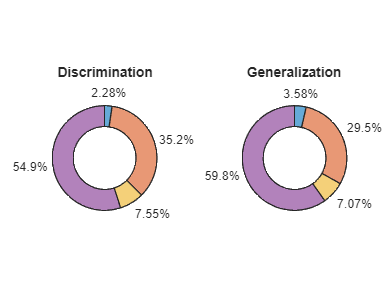

onlyPC_d = sum(All_d.CellComposition(:,3));
onlyHDC_d = sum(All_d.CellComposition(:,2));
both_d = sum(All_d.CellComposition(:,1));
none_d = sum(All_d.CellComposition(:,4))-onlyPC_d-onlyHDC_d-both_d;

onlyPC_g = sum(All_g.CellComposition(:,3));
onlyHDC_g = sum(All_g.CellComposition(:,2));
both_g = sum(All_g.CellComposition(:,1));
none_g = sum(All_g.CellComposition(:,4))-onlyPC_g-onlyHDC_g-both_g;

figure
tiledlayout(1,2)
nexttile;
donutchart([onlyHDC_d,onlyPC_d,  both_d, none_d])
title("Discrimination")

nexttile;
donutchart([onlyHDC_g, onlyPC_g,  both_g, none_g])
title("Generalization")

## Figure 6c - new version splitted into cohorts

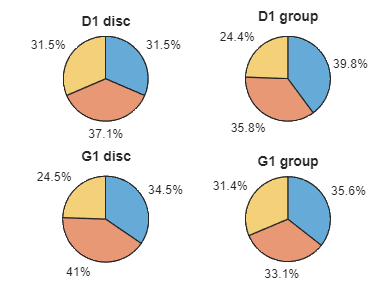

p_chi = 0.9905

cohorts = ["D1", "G1"];
figure
tiledlayout(2,2)

for i = 1:2 % loop on cohorts
    comp_d = GetComp([Cohort_d.TuningBin{i,1}; Cohort_d.TuningBin{i,2}]); % pool HDC/PC and HDC only (1st and 2nd cell in TuningBin)
    comp_g = GetComp([Cohort_g.TuningBin{i,1}; Cohort_g.TuningBin{i,2}]);


nexttile;
piechart(comp_d)
title(strcat(cohorts(i), " disc"))
nexttile;
piechart(comp_g)
title(strcat(cohorts(i), " group"))

x = [comp_d./sum(comp_d); comp_g./sum(comp_g)];
[h,p_chi, X2] = chi2cont(x);
p_chi

end


% get angular tuning 
% pool_HDC_d = cell(2,1);
% pool_HDC_g = cell(2,1);
% for i =1:2
% pool_HDC_d{i} = []; % pool conjunctive cells and HDC only cells
% pool_HDC_g{i} = [];
% for i =1:2
%     tuningbin_All = [Cohort_d.TuningBin{i,1}; Cohort_d.TuningBin{i,2}];
%     bothTuned = find(~isnan(Cohort_d.TuningBin{i}(:,2))  & ~isnan(Cohort_d.TuningBin{i}(:,1)));
%     pool_HDC_d{i} = [pool_HDC_d{i}; Cohort_d.AngleDiff{i}(bothTuned)];
% 
%     bothTuned = find(~isnan(Cohort_g.TuningBin{i}(:,2))  & ~isnan(Cohort_g.TuningBin{i}(:,1)));
%     pool_HDC_g{i} = [pool_HDC_g{i}; Cohort_g.AngleDiff{i}(bothTuned)];
% end
% [yd,xd] = ecdf(pool_HDC_d{i});
% [yg,xg] = ecdf(pool_HDC_g{i});
% 
% p = ranksum(pool_HDC_d{i}, pool_HDC_g{i})
% figure
% hold on
% plot(xd,yd, Color=colors(1))
% plot(xg,yg, Color=colors(4))
% axis square 
% box off
% xlabel("Angle")
% ylabel("Portion")
% legend("Discrimination", "Generalization", "Location","southeast")
% ylim([0 1])
% xlim([0 180])
% 
% end

function comp = GetComp(tunedBins)
      comp(1)= sum(~isnan(tunedBins(:,1))  & isnan(tunedBins(:,2))); % ctxt 1
      comp(2) = sum(~isnan(tunedBins(:,2))  & isnan(tunedBins(:,1)));% ctxt 2
       comp(3) = sum(~isnan(tunedBins(:,2))  & ~isnan(tunedBins(:,1)));  % both

end


## Figure 6d-e

figure
tiledlayout(2,3)
baseline_d = [1; 3; 3]./7.*100;
nexttile;
donutchart(baseline_d, {"Reward", "Light", "Other"})
observed_comp = cell(2,1);
title("By chance")
titles = ["Conjunctive", "HDC only"];
for i =1:2
    rew_d(i) = length(find(All_d.CategoricalTuning{i}(:,1) ==1 | All_d.CategoricalTuning{i}(:,2) ==1));
    light_d(i) = length(find(All_d.CategoricalTuning{i}(:,1) ==2 | All_d.CategoricalTuning{i}(:,2) ==2));
    other_d(i) = length(find(All_d.CategoricalTuning{i}(:,1) ==3 | All_d.CategoricalTuning{i}(:,2) ==3));
    norm_d(i) = rew_d(i)+light_d(i)+other_d(i);
    rew_d(i) = rew_d(i);
    light_d(i) = light_d(i);
    other_d(i) = other_d(i);
    nexttile;
    observed_comp{i} = [rew_d(i); light_d(i); other_d(i)]./norm_d(i).*100;
    donutchart(observed_comp{i}, {"Reward", "Light", "Other"})
    title(titles(i))
    x = [baseline_d observed_comp{i}];
    [h,p_chiD(i), X2_D(i)] = chi2cont(x);
    
end

observed_comp = cell(2,1);
nexttile;
baseline_g = [1, 4, 3]./8.*100;
donutchart(baseline_g, {"Reward", "Light", "Other"})
title("Baseline")
for i =1:2
    rew_g(i) = length(find(All_g.CategoricalTuning{i}(:,1) ==1 | All_g.CategoricalTuning{i}(:,2) ==1));
    light_g(i)  = length(find(All_g.CategoricalTuning{i}(:,1) ==2 | All_g.CategoricalTuning{i}(:,2) ==2));
    other_g(i)  = length(find(All_g.CategoricalTuning{i}(:,1) ==3 | All_g.CategoricalTuning{i}(:,2) ==3));
    norm_g(i) = rew_g(i) +light_g(i) +other_g(i) ;

    nexttile;
    observed_comp{i} = [rew_g(i); light_g(i); other_g(i)]./norm_g(i).*100;
    donutchart(observed_comp{i}, {"Reward", "Light", "Other"})
    title(titles(i))
    x = [baseline_d observed_comp{i}];
    [h,p_chiG(i), X2_G(i)] = chi2cont(x);
end

## Figure 6f-g

figure
bar(1, sum(All_d.HasRewardField, "omitnan")/sum(~isnan(All_d.HasRewardField))*100, "FaceColor", colors(1))
hold on
bar(2, sum(All_g.HasRewardField, "omitnan")/sum(~isnan(All_g.HasRewardField))*100, "FaceColor", colors(4))
box off
axis square
ylim([0 100])
xticks([1 2])
xticklabels(["Disc.", "Gen."])
ylabel("%")
title("Panel f")

figure
FieldRewDist_d = All_d.FieldDist(~isnan(All_d.FieldDist))*2; % convert in cm
FieldRewDist_g = All_g.FieldDist(~isnan(All_g.FieldDist))*2; % convert in cm
p = ranksum(FieldRewDist_d, FieldRewDist_g)
[yd,xd] = ecdf(FieldRewDist_d);
[yg,xg] = ecdf(FieldRewDist_g);

plot(xd,yd, Color=colors(1))
hold on
plot(xg,yg, Color=colors(4))
xline(10,"--")
box off
axis square
xlabel("Closest field from reward")
ylabel("Portion")
title("Panel g")
legend("Discrimination", "Generalization", "Location","southeast")
